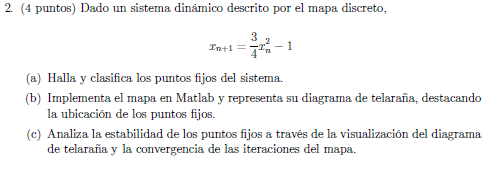

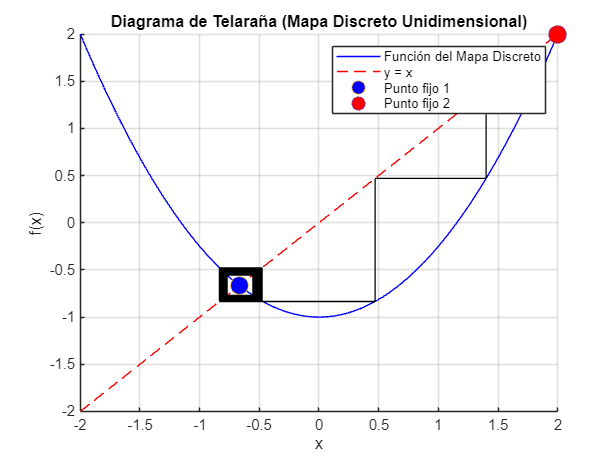

clear all

% Definir la función del mapa discreto unidimensional
f = @(x) 3/4*x.^2 - 1;

% Definir el rango de valores para x y el número de iteraciones
x_range = linspace(-2, 2, 1000);
num_iterations = 50;

% Visualizar el diagrama de telaraña
figure;
hold on;

% Plotear la función del mapa discreto
plot(x_range, f(x_range), 'b');

% Plotear la línea diagonal y=x
plot(x_range, x_range, 'r--');

syms xstar
% Encontrar los puntos fijos del mapa en función de mu
puntos_fijos = solve(3/4*xstar.^2 - 1 - xstar, xstar);
plot(puntos_fijos(1), f(puntos_fijos(1)), 'o', 'MarkerSize',12,'MarkerFaceColor','b')
plot(puntos_fijos(2), f(puntos_fijos(2)), 'o', 'MarkerSize',12,'MarkerFaceColor','r')

% Realizar las iteraciones del mapa discreto
x_init = 1.4; % Punto inicial arbitrario
for i = 1:num_iterations
    x_next = f(x_init);
    % Trazar la línea que conecta los puntos (x, f(x)) y (f(x), f(x))
    plot([x_init, x_init], [x_init, x_next], 'k');
    plot([x_init, x_next], [x_next, x_next], 'k');
    x_init = x_next;
    drawnow;
end

xlabel('x');
ylabel('f(x)');
title('Diagrama de Telaraña (Mapa Discreto Unidimensional)');
legend('Función del Mapa Discreto', 'y = x', 'Punto fijo 1', 'Punto fijo 2');
grid on;